# Part 1: Load and Prepare the RAVDESS Dataset

clear;
clc;
close all;

% Folder containing the RAVDESS speech dataset
datasetFolder = fullfile(pwd, 'Audio_Speech_Actors_01-24');

% Check whether the dataset folder exists
if ~isfolder(datasetFolder)
    error('Dataset folder not found. Please check the folder location.');
end

% Find all WAV files inside Actor_01 to Actor_24
allFiles = dir(fullfile(datasetFolder, '**', '*.wav'));

fprintf('Total WAV files found: %d\n', length(allFiles));

Total WAV files found: 1440



%% Part 1.1: Select Neutral Speech Recordings

% Prepare empty variables
filePaths = strings(0,1);
fileNames = strings(0,1);
speakerIDs = strings(0,1);
genderLabels = strings(0,1);
statementIDs = zeros(0,1);
repetitionIDs = zeros(0,1);

for i = 1:length(allFiles)

    % Get the filename
    currentName = string(allFiles(i).name);

    % Remove ".wav"
    nameWithoutExtension = erase(currentName, ".wav");

    % Split filename using "-"
    parts = split(nameWithoutExtension, "-");

    % RAVDESS filename should contain 7 numbers
    if length(parts) ~= 7
        continue;
    end

    % Read information from filename
    modality = str2double(parts(1));
    vocalChannel = str2double(parts(2));
    emotion = str2double(parts(3));
    statement = str2double(parts(5));
    repetition = str2double(parts(6));
    actorID = str2double(parts(7));

    % Keep only:
    % 03 = audio only
    % 01 = speech
    % 01 = neutral emotion
    if modality == 3 && vocalChannel == 1 && emotion == 1

        % Save full file path
        filePaths(end+1,1) = string( ...
            fullfile(allFiles(i).folder, allFiles(i).name));

        fileNames(end+1,1) = currentName;

        % Create Speaker ID
        speakerIDs(end+1,1) = ...
            "Actor_" + compose("%02d", actorID);

        % Odd actors = Male
        % Even actors = Female
        if mod(actorID,2) == 1
            genderLabels(end+1,1) = "Male";
        else
            genderLabels(end+1,1) = "Female";
        end

        statementIDs(end+1,1) = statement;
        repetitionIDs(end+1,1) = repetition;

    end

end

%% Part 1.2: Create Dataset Table

Dataset = table( ...
    fileNames, ...
    filePaths, ...
    speakerIDs, ...
    genderLabels, ...
    statementIDs, ...
    repetitionIDs, ...
    'VariableNames', ...
    {'FileName', ...
    'FilePath', ...
    'SpeakerID', ...
    'Gender', ...
    'Statement', ...
    'Repetition'});

disp(Dataset(1:min(10,height(Dataset)), :));

             FileName                                                       FilePath                                              SpeakerID      Gender     Statement    Repetition
    __________________________    ____________________________________________________________________________________________    __________    ________    _________    __________

    "03-01-01-01-01-01-01.wav"    "D:\elec5305\Report2_Meiqi_Song\Audio_Speech_Actors_01-24\Actor_01\03-01-01-01-01-01-01.wav"    "Actor_01"    "Male"          1            1     
    "03-01-01-01-01-02-01.wav"    "D:\elec5305\Report2_Meiqi_Song\Audio_Speech_Actors_01-24\Actor_01\03-01-01-01-01-02-01.wav"    "Actor_01"    "Male"          1            2     
    "03-01-01-01-02-01-01.wav"    "D:\elec5305\Report2_Meiqi_Song\Audio_Spe

%% Part 1.3: Check Dataset Balance

totalRecordings = height(Dataset);

maleCount = sum(Dataset.Gender == "Male");
femaleCount = sum(Dataset.Gender == "Female");

uniqueSpeakers = unique(Dataset.SpeakerID);
numberOfSpeakers = length(uniqueSpeakers);

fprintf('\nDataset Summary\n');


Dataset Summary


fprintf('Total recordings: %d\n', totalRecordings);

Total recordings: 96


fprintf('Male recordings: %d\n', maleCount);

Male recordings: 48


fprintf('Female recordings: %d\n', femaleCount);

Female recordings: 48


fprintf('Number of speakers: %d\n', numberOfSpeakers);

Number of speakers: 24



%% Part 2: Audio Pre-processing

targetFs = 22050;
numFiles = height(Dataset);

ProcessedAudio = cell(numFiles,1);
OriginalFs = zeros(numFiles,1);
ProcessedDuration = zeros(numFiles,1);

for i = 1:numFiles

    % Read audio file
    [x, fsOriginal] = audioread(Dataset.FilePath(i));

    % Convert stereo signal to mono
    if size(x,2) > 1
        x = mean(x,2);
    end

    % Remove DC component
    x = x - mean(x);

    % Resample to a common sampling frequency
    if fsOriginal ~= targetFs
        x = resample(x, targetFs, fsOriginal);
    end

    % Normalise amplitude
    x = x / (max(abs(x)) + eps);

    % Store processed signal
    ProcessedAudio{i} = x;

    % Store basic information
    OriginalFs(i) = fsOriginal;
    ProcessedDuration(i) = length(x) / targetFs;

end

fs = targetFs;

% Add preprocessing information to dataset table
Dataset.OriginalFs = OriginalFs;
Dataset.Duration = ProcessedDuration;

fprintf('\nAudio Pre-processing Completed\n');


Audio Pre-processing Completed


fprintf('Number of processed recordings: %d\n', numFiles);

Number of processed recordings: 96


fprintf('Target sampling frequency: %d Hz\n', targetFs);

Target sampling frequency: 22050 Hz


fprintf('Mean recording duration: %.2f seconds\n', mean(ProcessedDuration));

Mean recording duration: 3.50 seconds


%% Part 3: Acoustic Feature Extraction

numFiles = height(Dataset);
numMFCC = 13;

% Pre-allocate feature matrices
F0Features = NaN(numFiles,3);
MFCCFeatures = NaN(numFiles,numMFCC*2);
CentroidFeatures = NaN(numFiles,2);


for i = 1:numFiles

    % Get processed audio signal
    x = ProcessedAudio{i};

    % Make sure the signal is a column vector
    x = x(:);


    %% 3.1 Fundamental Frequency (F0)

    f0 = pitch(x,fs);

    % Keep valid F0 values within a reasonable speech range
    f0 = f0(isfinite(f0));
    f0 = f0(f0 >= 50 & f0 <= 400);

    if ~isempty(f0)

        meanF0 = mean(f0);
        medianF0 = median(f0);
        stdF0 = std(f0);

        F0Features(i,:) = ...
            [meanF0, medianF0, stdF0];

    end


    %% 3.2 MFCC

    mfccValues = mfcc(x,fs);

    % Make sure frames are stored in rows
    if size(mfccValues,1) == 13 || size(mfccValues,1) == 14

        if size(mfccValues,2) > 14
            mfccValues = mfccValues.';
        end

    end

    % MATLAB may return:
    % 14 columns = log energy + 13 MFCCs
    % 13 columns = 13 MFCCs only
    if size(mfccValues,2) == 14

        % Remove the first log-energy column
        mfccValues = mfccValues(:,2:14);

    elseif size(mfccValues,2) > 13

        % Keep the final 13 MFCC coefficients
        mfccValues = mfccValues(:,end-12:end);

    elseif size(mfccValues,2) < 13

        error(['MFCC extraction returned fewer than 13 coefficients ' ...
               'for recording %d.'],i);

    end

    % Remove invalid frames
    validMFCCRows = all(isfinite(mfccValues),2);
    mfccValues = mfccValues(validMFCCRows,:);

    if ~isempty(mfccValues)

        meanMFCC = mean(mfccValues,1);
        stdMFCC = std(mfccValues,0,1);

        MFCCFeatures(i,:) = ...
            [meanMFCC, stdMFCC];

    end


    %% 3.3 Spectral Centroid

    centroid = spectralCentroid(x,fs);

    centroid = centroid(isfinite(centroid));

    if ~isempty(centroid)

        meanCentroid = mean(centroid);
        stdCentroid = std(centroid);

        CentroidFeatures(i,:) = ...
            [meanCentroid, stdCentroid];

    end

end


%% 3.4 Create the Three Feature Sets

% Feature Set 1: F0
FeatureSet_F0 = F0Features;

% Feature Set 2: MFCC
FeatureSet_MFCC = MFCCFeatures;

% Feature Set 3: Combined
FeatureSet_Combined = ...
    [F0Features, MFCCFeatures, CentroidFeatures];


%% 3.5 Remove Recordings with Invalid Features

validRows = ...
    all(isfinite(FeatureSet_F0),2) & ...
    all(isfinite(FeatureSet_MFCC),2) & ...
    all(isfinite(CentroidFeatures),2);

Dataset = Dataset(validRows,:);

FeatureSet_F0 = FeatureSet_F0(validRows,:);
FeatureSet_MFCC = FeatureSet_MFCC(validRows,:);
FeatureSet_Combined = FeatureSet_Combined(validRows,:);

F0Features = F0Features(validRows,:);
MFCCFeatures = MFCCFeatures(validRows,:);
CentroidFeatures = CentroidFeatures(validRows,:);

ProcessedAudio = ProcessedAudio(validRows);


%% 3.6 Add Main Acoustic Features to Dataset Table

Dataset.MeanF0 = F0Features(:,1);
Dataset.MedianF0 = F0Features(:,2);
Dataset.StdF0 = F0Features(:,3);

Dataset.MeanSpectralCentroid = CentroidFeatures(:,1);
Dataset.StdSpectralCentroid = CentroidFeatures(:,2);


%% 3.7 Display Feature Extraction Summary

fprintf('\nAcoustic Feature Extraction Completed\n');


Acoustic Feature Extraction Completed



fprintf('Valid recordings: %d\n', ...
    height(Dataset));

Valid recordings: 96



fprintf('F0 features: %d\n', ...
    size(FeatureSet_F0,2));

F0 features: 3



fprintf('MFCC features: %d\n', ...
    size(FeatureSet_MFCC,2));

MFCC features: 26



fprintf('Combined features: %d\n', ...
    size(FeatureSet_Combined,2));

Combined features: 31


%% Part 4: Feature Analysis and Visualisation

close all;

% Create folder for saving result figures
figureFolder = fullfile(pwd,'Results_Figures');

if ~isfolder(figureFolder)
    mkdir(figureFolder);
end

% Separate male and female recordings
maleIdx = Dataset.Gender == "Male";
femaleIdx = Dataset.Gender == "Female";


%% 4.1 Mean F0 Distribution

figure;

histogram(Dataset.MeanF0(maleIdx), ...
    'Normalization','probability', ...
    'BinWidth',5);

hold on;

histogram(Dataset.MeanF0(femaleIdx), ...
    'Normalization','probability', ...
    'BinWidth',5);

grid on;

xlabel('Mean F0 (Hz)');
ylabel('Probability');

title('Distribution of Mean Fundamental Frequency');

legend('Male','Female','Location','best');

saveas(gcf, ...
    fullfile(figureFolder,'Figure1_MeanF0_Distribution.png'));


%% 4.2 Average F0 Comparison

maleF0Mean = mean(Dataset.MeanF0(maleIdx));
femaleF0Mean = mean(Dataset.MeanF0(femaleIdx));

maleF0Std = std(Dataset.MeanF0(maleIdx));
femaleF0Std = std(Dataset.MeanF0(femaleIdx));

f0MeanValues = [maleF0Mean femaleF0Mean];
f0StdValues = [maleF0Std femaleF0Std];

figure;

bar(1:2,f0MeanValues);

hold on;

errorbar(1:2, ...
    f0MeanValues, ...
    f0StdValues, ...
    'k.', ...
    'LineWidth',1.5);

grid on;

xticks([1 2]);
xticklabels({'Male','Female'});

xlabel('Gender');
ylabel('Mean F0 (Hz)');

title('Average Fundamental Frequency by Gender');

saveas(gcf, ...
    fullfile(figureFolder,'Figure2_Average_F0_Comparison.png'));


%% 4.3 Average MFCC Comparison

maleMFCC = mean(FeatureSet_MFCC(maleIdx,1:13),1);
femaleMFCC = mean(FeatureSet_MFCC(femaleIdx,1:13),1);

% Plot MFCC coefficients 2 to 13 for clearer comparison
mfccIndex = 2:13;

figure;

plot(mfccIndex, ...
    maleMFCC(mfccIndex), ...
    '-o', ...
    'LineWidth',1.5, ...
    'MarkerSize',5);

hold on;

plot(mfccIndex, ...
    femaleMFCC(mfccIndex), ...
    '-s', ...
    'LineWidth',1.5, ...
    'MarkerSize',5);

grid on;

xlabel('MFCC Coefficient Index');
ylabel('Average MFCC Value');

title('Average MFCC Coefficients (2-13)');

legend('Male','Female','Location','best');

saveas(gcf, ...
    fullfile(figureFolder,'Figure3_Average_MFCC_Comparison.png'));

%% 4.4 Spectral Centroid Comparison

maleSCMean = ...
    mean(Dataset.MeanSpectralCentroid(maleIdx));

femaleSCMean = ...
    mean(Dataset.MeanSpectralCentroid(femaleIdx));

maleSCStd = ...
    std(Dataset.MeanSpectralCentroid(maleIdx));

femaleSCStd = ...
    std(Dataset.MeanSpectralCentroid(femaleIdx));

scMeanValues = [maleSCMean femaleSCMean];
scStdValues = [maleSCStd femaleSCStd];

figure;

bar(1:2,scMeanValues);

hold on;

errorbar(1:2, ...
    scMeanValues, ...
    scStdValues, ...
    'k.', ...
    'LineWidth',1.5);

grid on;

xticks([1 2]);
xticklabels({'Male','Female'});

xlabel('Gender');
ylabel('Mean Spectral Centroid (Hz)');

title('Average Spectral Centroid by Gender');

saveas(gcf, ...
    fullfile(figureFolder,'Figure4_SpectralCentroid_Comparison.png'));


%% 4.5 Display Numerical Summary

fprintf('\nFeature Analysis Completed\n');


Feature Analysis Completed



fprintf('\nMean F0:\n');


Mean F0:


fprintf('Male   = %.2f Hz\n',maleF0Mean);

Male   = 231.83 Hz


fprintf('Female = %.2f Hz\n',femaleF0Mean);

Female = 233.55 Hz



fprintf('\nMean Spectral Centroid:\n');


Mean Spectral Centroid:


fprintf('Male   = %.2f Hz\n',maleSCMean);

Male   = 1153.83 Hz


fprintf('Female = %.2f Hz\n',femaleSCMean);

Female = 1595.21 Hz



fprintf('\nFour result figures have been saved in Results_Figures.\n');


Four result figures have been saved in Results_Figures.


%% Part 5: Classification and Evaluation

close all;

% Labels and speaker IDs
Labels = string(Dataset.Gender);
SpeakerIDs = string(Dataset.SpeakerID);

numRecordings = height(Dataset);

% Three feature sets
FeatureSets = {
    FeatureSet_F0
    FeatureSet_MFCC
    FeatureSet_Combined
};

FeatureNames = {
    'F0'
    'MFCC'
    'Combined'
};

numFeatureSets = 3;
numFolds = 5;


%% 5.1 Create Speaker-Independent 5-Fold Assignment

uniqueSpeakers = unique(SpeakerIDs);

maleSpeakers = strings(0,1);
femaleSpeakers = strings(0,1);

for i = 1:length(uniqueSpeakers)

    idx = SpeakerIDs == uniqueSpeakers(i);
    speakerGender = Labels(find(idx,1));

    if speakerGender == "Male"
        maleSpeakers(end+1,1) = uniqueSpeakers(i);
    else
        femaleSpeakers(end+1,1) = uniqueSpeakers(i);
    end

end

speakerFold = zeros(length(uniqueSpeakers),1);

% Assign male speakers across five folds
for i = 1:length(maleSpeakers)

    speakerIndex = find(uniqueSpeakers == maleSpeakers(i));

    speakerFold(speakerIndex) = ...
        mod(i-1,numFolds) + 1;

end

% Assign female speakers across five folds
for i = 1:length(femaleSpeakers)

    speakerIndex = find(uniqueSpeakers == femaleSpeakers(i));

    speakerFold(speakerIndex) = ...
        mod(i-1,numFolds) + 1;

end


%% 5.2 Prepare Result Storage

AccuracyResults = zeros(numFeatureSets,2);

% Columns:
% 1 = F0 KNN
% 2 = F0 SVM
% 3 = MFCC KNN
% 4 = MFCC SVM
% 5 = Combined KNN
% 6 = Combined SVM

AllPredictions = strings(numRecordings,6);

experimentColumn = 0;


%% 5.3 Run KNN and SVM for Each Feature Set

for featureIndex = 1:numFeatureSets

    X = FeatureSets{featureIndex};

    predictionKNN = strings(numRecordings,1);
    predictionSVM = strings(numRecordings,1);


    for fold = 1:numFolds

        testSpeakers = ...
            uniqueSpeakers(speakerFold == fold);

        testIdx = ismember(SpeakerIDs,testSpeakers);

        trainIdx = ~testIdx;


        % Training and testing data
        XTrain = X(trainIdx,:);
        XTest = X(testIdx,:);

        YTrain = Labels(trainIdx);


        %% Standardise using training data only

        trainMean = mean(XTrain,1);
        trainStd = std(XTrain,0,1);

        trainStd(trainStd == 0) = 1;

        XTrain = ...
            (XTrain - trainMean) ./ trainStd;

        XTest = ...
            (XTest - trainMean) ./ trainStd;


        %% KNN Classification

        k = 5;

        predictionKNN(testIdx) = ...
            manualKNN( ...
            XTrain, ...
            YTrain, ...
            XTest, ...
            k);


        %% Linear SVM Classification

        svmModel = ...
            trainLinearSVM( ...
            XTrain, ...
            YTrain);

        predictionSVM(testIdx) = ...
            predictLinearSVM( ...
            svmModel, ...
            XTest);

    end


    %% Calculate Accuracy

    accuracyKNN = ...
        mean(predictionKNN == Labels);

    accuracySVM = ...
        mean(predictionSVM == Labels);

    AccuracyResults(featureIndex,1) = ...
        accuracyKNN;

    AccuracyResults(featureIndex,2) = ...
        accuracySVM;


    %% Store Predictions

    experimentColumn = ...
        (featureIndex-1)*2 + 1;

    AllPredictions(:,experimentColumn) = ...
        predictionKNN;

    AllPredictions(:,experimentColumn+1) = ...
        predictionSVM;

end


%% 5.4 Display Classification Results

ResultsTable = table( ...
    string(FeatureNames), ...
    AccuracyResults(:,1)*100, ...
    AccuracyResults(:,2)*100, ...
    'VariableNames', ...
    {'Feature_Set','KNN_Accuracy','SVM_Accuracy'});

disp(ResultsTable);

    Feature_Set    KNN_Accuracy    SVM_Accuracy
    ___________    ____________    ____________

    "F0"              88.542          67.708   
    "MFCC"             81.25          57.292   
    "Combined"        82.292          55.208   



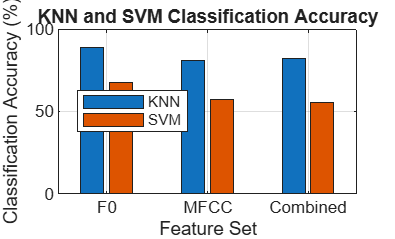



%% 5.5 Figure 5: Accuracy Comparison

figure;

bar(AccuracyResults*100,'grouped');

grid on;

xticks(1:3);

xticklabels(FeatureNames);

xlabel('Feature Set');
ylabel('Classification Accuracy (%)');

title('KNN and SVM Classification Accuracy');

legend( ...
    'KNN', ...
    'SVM', ...
    'Location','best');

ylim([0 100]);

saveas(gcf, ...
    fullfile(figureFolder, ...
    'Figure5_Classification_Accuracy.png'));

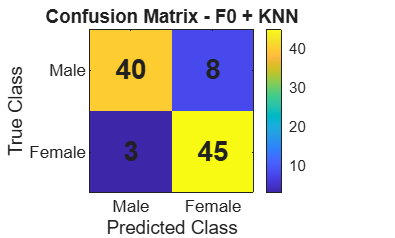



%% 5.6 Find Best Performing Experiment

allAccuracy = [
    AccuracyResults(1,1)
    AccuracyResults(1,2)
    AccuracyResults(2,1)
    AccuracyResults(2,2)
    AccuracyResults(3,1)
    AccuracyResults(3,2)
];

experimentNames = [
    "F0 + KNN"
    "F0 + SVM"
    "MFCC + KNN"
    "MFCC + SVM"
    "Combined + KNN"
    "Combined + SVM"
];

[bestAccuracy,bestExperiment] = ...
    max(allAccuracy);

bestPredictions = ...
    AllPredictions(:,bestExperiment);


%% 5.7 Calculate Confusion Matrix

actualMale = Labels == "Male";
actualFemale = Labels == "Female";

predMale = bestPredictions == "Male";
predFemale = bestPredictions == "Female";

maleCorrect = ...
    sum(actualMale & predMale);

maleAsFemale = ...
    sum(actualMale & predFemale);

femaleAsMale = ...
    sum(actualFemale & predMale);

femaleCorrect = ...
    sum(actualFemale & predFemale);

ConfusionMatrix = [
    maleCorrect     maleAsFemale
    femaleAsMale    femaleCorrect
];


%% 5.8 Figure 6: Best Model Confusion Matrix

figure;

imagesc(ConfusionMatrix);

axis equal;
axis tight;

colorbar;

xticks([1 2]);
xticklabels({'Male','Female'});

yticks([1 2]);
yticklabels({'Male','Female'});

xlabel('Predicted Class');
ylabel('True Class');

title( ...
    sprintf( ...
    'Confusion Matrix - %s', ...
    experimentNames(bestExperiment)));

for row = 1:2

    for col = 1:2

        text( ...
            col, ...
            row, ...
            num2str(ConfusionMatrix(row,col)), ...
            'HorizontalAlignment','center', ...
            'FontSize',14, ...
            'FontWeight','bold');

    end

end

saveas(gcf, ...
    fullfile(figureFolder, ...
    'Figure6_Best_Model_Confusion_Matrix.png'));



%% 5.9 Display Final Summary

fprintf('\nClassification Completed\n');


Classification Completed



fprintf( ...
    'Best model: %s\n', ...
    experimentNames(bestExperiment));

Best model: F0 + KNN



fprintf( ...
    'Best accuracy: %.2f%%\n', ...
    bestAccuracy*100);

Best accuracy: 88.54%



fprintf('\nClassification figures saved in Results_Figures.\n');


Classification figures saved in Results_Figures.




%% Local Function 1: Manual KNN

function predictions = manualKNN( ...
    XTrain,YTrain,XTest,k)

    numTest = size(XTest,1);

    predictions = strings(numTest,1);

    for i = 1:numTest

        difference = ...
            XTrain - XTest(i,:);

        distances = ...
            sqrt(sum(difference.^2,2));

        [~,order] = sort(distances);

        neighbourLabels = ...
            YTrain(order(1:k));

        maleVotes = ...
            sum(neighbourLabels == "Male");

        femaleVotes = ...
            sum(neighbourLabels == "Female");

        if maleVotes >= femaleVotes

            predictions(i) = "Male";

        else

            predictions(i) = "Female";

        end

    end

end


%% Local Function 2: Train Linear SVM

function model = trainLinearSVM(XTrain,YTrain)

    y = ones(length(YTrain),1);

    y(YTrain == "Male") = -1;
    y(YTrain == "Female") = 1;

    numFeatures = size(XTrain,2);

    w = zeros(numFeatures,1);
    b = 0;

    lambda = 0.01;
    numEpochs = 500;

    for epoch = 1:numEpochs

        scores = ...
            y .* (XTrain*w + b);

        active = scores < 1;

        if any(active)

            gradW = ...
                lambda*w - ...
                mean( ...
                XTrain(active,:)' * ...
                y(active));

            gradB = ...
                -mean(y(active));

        else

            gradW = lambda*w;
            gradB = 0;

        end

        learningRate = ...
            0.01 / sqrt(epoch);

        w = ...
            w - learningRate*gradW;

        b = ...
            b - learningRate*gradB;

    end

    model.w = w;
    model.b = b;

end


%% Local Function 3: Predict Linear SVM

function predictions = ...
    predictLinearSVM(model,XTest)

    scores = ...
        XTest*model.w + model.b;

    predictions = strings(size(scores));

    predictions(scores < 0) = "Male";
    predictions(scores >= 0) = "Female";

end